close all;
clear;
clc;

%Init

load 'dreiTank.mat'

T = 300; % Simulationsdauer (Sekunden)

t = T/parameter.dt;
time = linspace(parameter.dt,T,t);

x0 = zeros(3,1);
xOut = zeros(3,t);
yOut = zeros(3,t);
dxOut = zeros(3,t);
uOut = zeros(1,t);

%Simulation
for k = 1 : t
    if k == 1
        [xOut(:,k),yOut(:,k)] = solveThreeTank(x0,parameter);
        dxOut(:,k) = xOut(:,k) - x0;
    else
        [xOut(:,k),yOut(:,k)] = solveThreeTank(xOut(:,k-1),parameter);
        dxOut(:,k) = xOut(:,k) - xOut(:,k-1);
    end
    uOut(k) = parameter.u; 
end

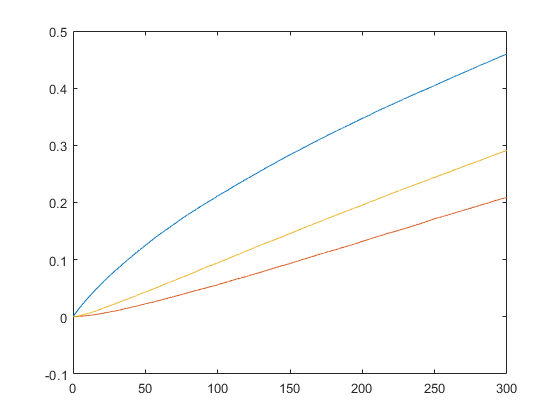

%plot results
figure(1)
plot(time, xOut(1,:),time, xOut(2,:),time, xOut(3,:))

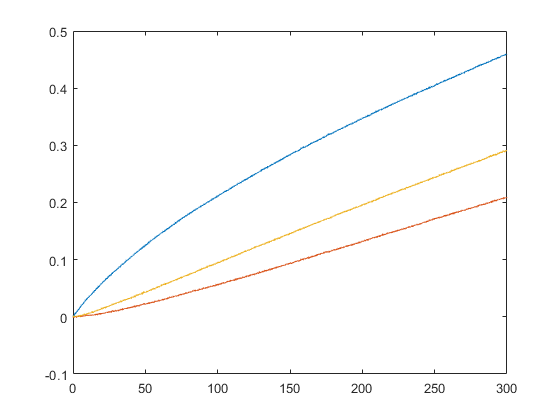


figure(2)
plot(time, yOut(1,:),time, yOut(2,:),time, yOut(3,:))

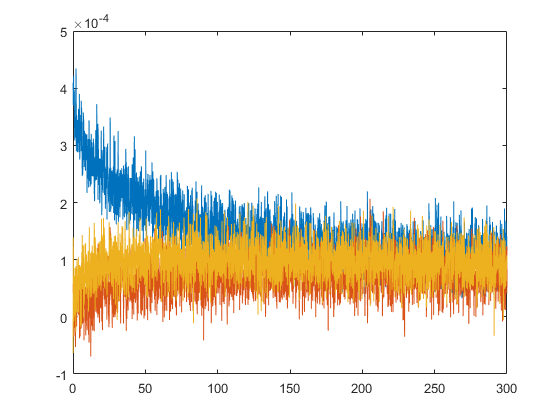


figure(3)
plot(time, dxOut(1,:),time, dxOut(2,:),time, dxOut(3,:))

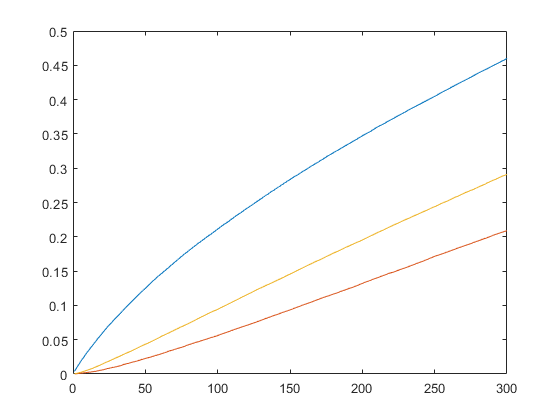

xOut = xOut.';
yOut = yOut.';
uOut = uOut.';
dxOut = dxOut.';
time = time.';

%create training data
xTrain = xOut(10 : 10:end,:);
yTrain = yOut(10 : 10:end,:);
uTrain = uOut(10 : 10:end,:);
dxTrain = dxOut(10 : 10:end,:);
timeTrain = time(10 : 10:end);

figure(4)
plot(timeTrain, xTrain(:,1),timeTrain, xTrain(:,2),timeTrain, xTrain(:,3))

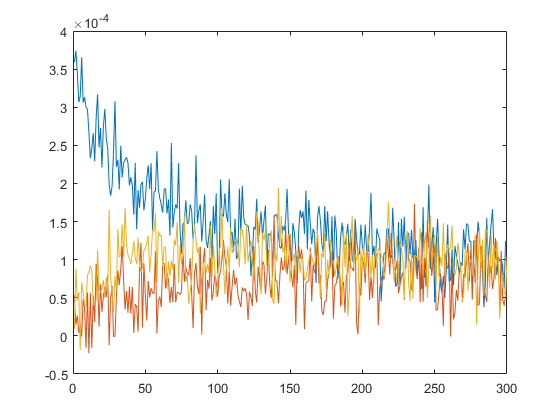


figure(5)
plot(timeTrain, dxTrain(:,1),timeTrain, dxTrain(:,2),timeTrain, dxTrain(:,3))

save ('threeTankData','xTrain',"yTrain","uTrain","dxTrain","timeTrain");